# Microarray Data Analysis

In this tutorial, we will analyze microarray data available from the Gene Expression Omnibus (GEO) repository hosted at NCBI ([http://www.ncbi.nlm.nih.gov/geo/](http://www.ncbi.nlm.nih.gov/geo/)). We will rely on MATLAB's *Bioinformatics Toolbox* for some of the file parsing and data analysis functionality.

We'll analyze the experimental daata that was used in the following study: *"A stromal gene signature associated with inflammatory breast cancer.", Boersma et.al., 2008. *[https://www.ncbi.nlm.nih.gov/pubmed/17999412](https://www.ncbi.nlm.nih.gov/pubmed/17999412)

**Abstract:** The factors that determine whether a breast carcinoma will develop into inflammatory breast cancer (IBC) remain poorly understood. Recent evidence indicates that the tumor stroma influences cancer phenotypes. We tested the hypotheses that the gene expression signature of the tumor stroma is a distinctive feature of IBC. We used laser capture microdissection to obtain enriched populations of tumor epithelial cells and adjacent stromal cells from 15 patients with IBC and 35 patients with invasive, noninflammatory breast cancer (non-IBC). Their mRNA expression profiles were assessed using Affymetrix GeneChips. In addition, a previously established classifier for IBC was evaluated for the resulting data sets. The gene expression profile of the tumor stroma distinguished IBC from non-IBC, and a previously established IBC prediction signature performed better in classifying IBC using the gene expression profile of the tumor stroma than it did using the profile of the tumor epithelium. In a pathway analysis, the genes differentially expressed between IBC and non-IBC tumors clustered in distinct pathways. We identified multiple pathways related to the endoplasmic stress response that could be functionally significant in IBC. Our findings suggest that the gene expression in the tumor stroma may play a role in determining the IBC phenotype.

The data is available at [https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE5847](https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE5847)

## GEO Data Types

- `GSM`: An individual microarray sample (e.g., patient, or tissue).

- `GSE`: A series, representing an experimental study. A `GSE` contains one or more `GSM` entries.

- `GPL`: Platform data, containing information about microarray probes. Each `GSM` sample is associated with a `GPL`. E.g., to find out the gene symbols for a GSM, you would need to consult with the GPL used in that study.

## Variable Names and Terms

- `GSE`: The struct returned from `getgeodata()`. Contains all the information contained in a GSE.

- d: The DataMatrix object representing the GSE data. We'll also use the prefix d to denote other DataMatrix objects, e.g., dpvals.

- m: A numerical matrix (e.g., converting d into a double).

- MAP_GSE_GPL: used to map gse probes to gpl indices, so we can get e.g., gene symbol information for a probe. IBC: inflammatory breast cancer Epithelial: the type of cells forming the breast cancer Stroma: fatty tissue (adipocytes) and fibroblasts

## Objectives

- Understand the gene expression using microarray.

- Differential Gene Expression Analysis

- Familiar with the GEO repository hosted at NCBI

- Understand the GEO data matrix structure, GSE and GPL

- Download GEO data

- Map container using `containers.Map()`

- Logical Indexing

- Clustering and PCA

- Volcano Plot

# Download & Parse GSE Data

% gse.Header & gse.data -> 2283 probes & 95 samples
gse = loadGEO('GSE5847')

Retreiving GSE5847 from GEO...


gse = struct with fields:
    Header: [1×1 struct]
      Data: [22283×95 bioma.data.DataMatrix]

% gse.Data is a DataMatrix object, similar to a MATLAB table. In addition,
% to get the numerical matrix, it internally stores the row & column names.
get(gse.Data)

            Name: ''
        RowNames: {22283×1 cell}
        ColNames: {1×95 cell}
           NRows: 22283
           NCols: 95
           NDims: 2
    ElementClass: 'double'


**Print rownames, columnnames, first 6 probes, and first 5 samples. There is only probe information, no gene symbol information. Rows (probes), columns (sample names), data is the flourescent intensity.**

gse.Data.RowNames

ans = 22283×1 cell array
    {'1007_s_at'  }
    {'1053_at'    }
    {'117_at'     }
    {'121_at'     }
    {'1255_g_at'  }
    {'1294_at'    }
    {'1316_at'    }
    {'1320_at'    }
    {'1405_i_at'  }
    {'1431_at'    }
    {'1438_at'    }
    {'1487_at'    }
    {'1494_f_at'  }
    {'1598_g_at'  }
    {'160020_at'  }
    {'1729_at'    }
    {'1773_at'    }
    {'177_at'     }
    {'179_at'     }
    {'1861_at'    }
    {'200000_s_at'}
    {'200001_at'  }
    {'200002_at'  }
    {'200003_s_at'}
    {'200004_at'  }
    {'200005_at'  }
    {'200006_at'  }
    {'200007_at'  }
    {'200008_s_at'}
    {'200009_at'  }

gse.Data.ColNames

ans = 1×95 cell array
    {'GSM136326'}    {'GSM136327'}    {'GSM136328'}    {'GSM136329'}    {'GSM136330'}    {'GSM136331'}    {'GSM136332'}    {'GSM136333'}    {'GSM136334'}    {'GSM136335'}    {'GSM136336'}    {'GSM136337'}    {'GSM136338'}    {'GSM136339'}    {'GSM136340'}    {'GSM136341'}    {'GSM136342'}    {'GSM136343'}    {'GSM136344'}    {'GSM136345'}    {'GSM136346'}    {'GSM136347'}    {'GSM136348'}    {'GSM136349'}    {'GSM136350'}    {'GSM136351'}    {'GSM136352'}    {'GSM136353'}    {'GSM136354'}    {'GSM136355'}    {'GSM136356'}    {'GSM136357'}    {'GSM136358'}    {'GSM136359'}    {'GSM136360'}    {'GSM136361'}    {'GSM136362'}    {'GSM136363'}    {'GSM136364'}    {'GSM136365'}    {'GSM136366'}    {'GSM136367'}    {'GSM136368'}    {'GSM136369'}    {'GSM136370'}    {'GSM136371'}    {'GSM136372'}    {'GSM136373'}    {'GSM136374'}    {'GSM136375'}    {'GSM136376'}    {'GSM136377'}    {'GSM136378'}    {'GSM136379'}    {'GSM136380'}    {'GSM136381'}    {'GSM136382'}    {'GSM

gse.Data(1:6, 1:5)

ans = 
                 GSM136326    GSM136327    GSM136328    GSM136329    GSM136330
    1007_s_at     10.45       9.3995       9.4248       9.4729       9.2788   
    1053_at      5.7195       4.8493       4.7321       4.7289       5.3264   
    117_at       5.9387       6.0833        6.448       6.1769       6.5446   
    121_at       8.0231       7.8947        8.345       8.1632       8.2338   
    1255_g_at    3.9548       3.9632       3.9641       4.0878       3.9989   
    1294_at       7.909        8.364       8.2719       8.3582          7.7   


## GSE Header Information (Series & Sample Structures)

gse.Header

ans = struct with fields:
     Series: [1×1 struct]
    Samples: [1×1 struct]

gse.Header.Series

ans = struct with fields:
                         title: 'Tumor and stroma from breast by LCM'
                 geo_accession: 'GSE5847'
                        status: 'Public on Sep 30 2007'
               submission_date: 'Sep 15 2006'
              last_update_date: 'Mar 18 2020'
                     pubmed_id: '17999412↵19225562↵20978357'
                       summary: 'Tumor epithelium and surrounding stromal cells were isolated using laser capture microdissection of human breast cancer to examine differences in gene expression based on tissue types from inflammatory and non-inflammatory breast cancer↵Keywords: LCM'
                overall_design: 'We applied LCM to obtain samples enriched in tumor epithelium and stroma from 15 IBC and 35 non-IBC cases to study the relative contribution of each component to the IBC phenotype and to patient survival. '
                          type: 'Expression profiling by array'
                   contributor: 'Stefan,,Ambs↵Brenda,,Boersma↵Ma

gse.Header.Samples

ans = struct with fields:
                         title: {1×95 cell}
                 geo_accession: {1×95 cell}
                        status: {1×95 cell}
               submission_date: {1×95 cell}
              last_update_date: {1×95 cell}
                          type: {1×95 cell}
                 channel_count: {1×95 cell}
               source_name_ch1: {1×95 cell}
                  organism_ch1: {1×95 cell}
           characteristics_ch1: {7×95 cell}
                  molecule_ch1: {1×95 cell}
          extract_protocol_ch1: {1×95 cell}
                     label_ch1: {1×95 cell}
            label_protocol_ch1: {1×95 cell}
                     taxid_ch1: {1×95 cell}
                  hyb_protocol: {1×95 cell}
                 scan_protocol: {1×95 cell}
                   description: {1×95 cell}
               data_processing: {1×95 cell}
                   platform_id: {1×95 cell}
                  contact_name: {1×95 cell}
            contact_laboratory: {1×95 cell}
      

**Get sample titles & accession**

gse.Header.Samples.title{1}

ans = 'LCM stroma sample from patient #37'

gse.Header.Samples.title{90}

ans = 'LCM tumor epithelium sample from patient #34'

gse.Header.Samples.geo_accession{1}

ans = 'GSM136326'

**Print all of the available characteristics for the 20th sample**

gse.Header.Samples.characteristics_ch1(:, 20)

ans = 7×1 cell array
    {'diagnosis: non-IBC'     }
    {'status: Alive'          }
    {'patient_id: 8'          }
    {'race: European American'}
    {'tnm_stage: IIA'         }
    {'er_status: POS'         }
    {'tissue: Stroma'         }

Print the diagnostic information of all samples

gse.Header.Samples.characteristics_ch1(1, :)

ans = 1×95 cell array
    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis:

Print the sample source for all samples

gse.Header.Samples.source_name_ch1

ans = 1×95 cell array
    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer 

Print the GPL platform used in this study (each manufacturer has its own array and probe sets).

gse.Header.Series.platform_id

ans = 'GPL96'

## GPL Information Is Contained In a Separate File. Download and parse it.

gpl = loadGEO('GPL96')

Retreiving GPL96 from GEO...


gpl = struct with fields:
                 Scope: 'PLATFORM'
             Accession: 'GPL96'
                Header: [1×1 struct]
    ColumnDescriptions: {16×1 cell}
           ColumnNames: {16×1 cell}
                  Data: {22283×16 cell}

Here;s the type of information we get for each microarray Probe. We are most interested in `gpl.ColumnNames` and `gpl.data.`

gpl.Scope

ans = 'PLATFORM'

gpl.Header

ans = struct with fields:
    Type: 'Gene Expression Omnibus'
    Text: [43345×600 char]

gpl.ColumnNames

ans = 16×1 cell array
    {'ID'                              }
    {'GB_ACC'                          }
    {'SPOT_ID'                         }
    {'Species Scientific Name'         }
    {'Annotation Date'                 }
    {'Sequence Type'                   }
    {'Sequence Source'                 }
    {'Target Description'              }
    {'Representative Public ID'        }
    {'Gene Title'                      }
    {'Gene Symbol'                     }
    {'ENTREZ_GENE_ID'                  }
    {'RefSeq Transcript ID'            }
    {'Gene Ontology Biological Process'}
    {'Gene Ontology Cellular Component'}
    {'Gene Ontology Molecular Function'}

gpl.Data(1, 4)

ans = 1×1 cell array
    {'Homo sapiens'}

## Translate Probesets to Gene Symbols ( The goal is to replace `gse.Data.RowNames` with the gene symbols from gpl)

!platform_table_begin(probe id links gpl and gse data)

gplprobes = gpl.Data(:, strcmp(gpl.ColumnNames, 'ID')); % assign the gpl probes
gplgenes = gpl.Data(:, strcmp(gpl.ColumnNames, 'Gene Symbol')); % assign the gpl gene symbols
gseprobes = gse.Data.rownames; % assign gse probes
gseprobes{1}

ans = '1007_s_at'

% What is the difference between gplprobes and gseprobes
%   Not all probes in a given platform will be present in the GSE series. 
%   gseprobes is a subset of gpl probes

% Preallocate a map to annotate gse probes
MAP_GSE_GPL = zeros(numel(gseprobes), 1);

% For each gseprobe, we need to search gplprobes and use the corresponding
% gene. 
% Doing a string comparison for each of them would be too slow. Lets use a
% Map container to speed this up.
% M = containers.Map(keySet,valueSet), https://www.mathworks.com/help/matlab/ref/containers.map.html
% index (key) the gplprobes
map = containers.Map(gplprobes, 1:numel(gplprobes))

map =   Map with properties:
        Count: 22283
      KeyType: char
    ValueType: double

% The map object maps a `keyset` to a `valueset` analagous to a python
% dictionary where the names are the `keyset` and the values the `valueset`.
% Thus, once can use the map object to 'search' for a corresponding value
% for every key.
% In our case, the keys are probes, and the values are unique numbers
map ('1007_s_at')

ans = 1

map ('121_at')

ans = 4

% Loop through all the gseprobes to assign the index(key) to MAP_GSE_GPL
% based on gseprobes
% map.isKey(gseprobes{i}) check if gseprobes{i} belongs to one of the keys.
% If yes, MAP_GSE_GPL(i) will have the same key.
for i = 1:numel(gseprobes)
	if map.isKey(gseprobes{i}); MAP_GSE_GPL(i) = map( gseprobes{i} ); end
end
MAP_GSE_GPL(1:10)

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


gseprobes (MAP_GSE_GPL(1))

ans = 1×1 cell array
    {'1007_s_at'}

gseprobes{MAP_GSE_GPL(4)}

ans = '121_at'

% Now, try to assign the gene symbols to gsegenes
% first make a copy, store gene names and entries not found will keep the probe name.
gsegenes = gseprobes; 

% find(MAP_GSE_GPL) return a non-zeroindex
MAP_GSE_GPL(find(MAP_GSE_GPL)) % Return values of MAP_GSE_GPL

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


% link probes to gene names
gsegenes(find(MAP_GSE_GPL)) = gplgenes(MAP_GSE_GPL(find(MAP_GSE_GPL)));

% Print first 5 probes and the gene symbols we found for them. We convert
% to table() just because we like how it prints.
table(gseprobes(1:5), gsegenes(1:5),'VariableNames',{'gseprobe','gsegene'})

ans = 5×2 table
      gseprobe             gsegene       
    _____________    ____________________
    {'1007_s_at'}    {'DDR1 /// MIR4640'}
    {'1053_at'  }    {'RFC2'            }
    {'117_at'   }    {'HSPA6'           }
    {'121_at'   }    {'PAX8'            }
    {'1255_g_at'}    {'GUCA1A'          }

**TODO: the above code is useful. Think about generalizing it to a function that takes gpl structure and gseprobes and returns any GPL column (e.g., genesymbol, refseq id, etc.) you need.**

% Test custom probe annotation function
t = annotateProbes(gse, gpl);
head(t, 5)

ans = 5×2 table
         ID              Gene Symbol     
    _____________    ____________________
    {'1007_s_at'}    {'DDR1 /// MIR4640'}
    {'1053_at'  }    {'RFC2'            }
    {'117_at'   }    {'HSPA6'           }
    {'121_at'   }    {'PAX8'            }
    {'1255_g_at'}    {'GUCA1A'          }

**Let's replace the DataMatrix object so it uses genes as rownames. **We would've liked to say `d.rownames = gsegenes` but `DataMatrix` doesn't support that.

gse.Data = gse.Data.rownames(':', t.("Gene Symbol"));

Print a random selection of rows and columns

gse.Data( randi(gse.Data.size(1),1,6), randi(gse.Data.size(2),1,6) )

ans = 
               GSM136352    GSM136377    GSM136416    GSM136417    GSM136340    GSM136418
    KATNBL1    4.9503       5.0613       5.5847        5.582       4.8949       5.1698   
               4.3302       4.8315       4.7682       4.7793       4.3527       4.7008   
    DYNLT3     9.0097       8.6276       9.5227       8.2726        8.117       9.6047   
    AMN        6.7465       7.0929       6.7819       7.1261       6.5902       6.7907   
    ZNF160     8.8644       8.8452       7.3929       8.2202       8.6351        8.899   
    CSDE1      8.9715       8.9252       10.409       9.7232       9.6099        10.41   


## Data Analysis: Find Differentially Expressed Genes Betweeen Groups of Samples

IBC vs non-IBC samples; Stroma vs. Epithelium; IBC (stroma) vs. IBC (epithelium) and so forth.

% Modify (clean) grouping variables
sourceClean = @(x) strtrim(regexp(x, '(stroma|tumor epithelium)', 'match'));
gse.Header.Samples.source_name_ch1 = cellfun(sourceClean, gse.Header.Samples.source_name_ch1);
groupClean = @(x) strtrim(regexp(x, '( IBC$|non-IBC$)', 'match'));
gse.Header.Samples.characteristics_ch1(1,:) = cellfun(groupClean, gse.Header.Samples.characteristics_ch1(1,:));

### Determine Sample Groups We'll Work With

We are often interested in comparing groups of samples. We need to look at their header information and decide which information for samples we can use to group them. For this experiment, we'll work with four groups, using IBC vs. non-IBC and stroma vs. epithelial characteristics. Where one finds the sample information is experiment-specific, but the Header.Samples structure usually contains what we need.

The first `characteristics_ch1` contains diagnosis info (IBC vs. non-IBC) (take a look at the GSE58 47 excel sheet).

samplegroups = gse.Header.Samples.characteristics_ch1(1, :);
unique(samplegroups)

ans = 1×2 cell array
    {'IBC'}    {'non-IBC'}

`source_name_ch1` contains tissue source info (stroma vs. epithelium) (take a look at the GSE5847 excel sheet).

samplesources = gse.Header.Samples.source_name_ch1;
unique(samplesources)

ans = 1×2 cell array
    {'stroma'}    {'tumor epithelium'}

% Create logical vectors to record which samples are IBC and which are
% stroma
IBC = strcmp(samplegroups, 'IBC');
stroma = strcmp(samplesources, 'stroma');
% Separate patients in the 4 different groups with 4 logical arrays
mask.stroma_ibc = stroma & IBC;
mask.stroma_noibc = stroma & ~IBC;
mask.epi_ibc = ~stroma & IBC;
mask.epi_noibc = ~stroma & ~IBC;

% Assign Each sample to a corresponding group
gse.Header.Samples.Group = cell(1, size(gse.Data, 2));
gse.Header.Samples.Group(mask.stroma_ibc) = {'sIBC'}; % sIBC = 1
gse.Header.Samples.Group(mask.stroma_noibc) = {'s~IBC'}; % s~IBC = 2
gse.Header.Samples.Group(mask.epi_ibc) = {'eIBC'}; % eIBC = 3
gse.Header.Samples.Group(mask.epi_noibc) = {'e~IBC'}; % e~IBC = 4

Igroups=zeros(1,numel(samplegroups));
Igroups(mask.stroma_ibc) = 1;
Igroups(mask.stroma_noibc) = 2;
Igroups(mask.epi_ibc) = 3;
Igroups(mask.epi_noibc) = 4;
groupnames={'sIBC' 's~IBC' 'eIBC' 'e~IBC'};

% Replace column names with groups
gse.Data = gse.Data.colnames(':', gse.Header.Samples.Group); % this really means: "d.colnames = colnames"

print random selection of rows and columns

gse.Data( randi(gse.Data.size(1),1,6), randi(gse.Data.size(2),1,6) )

ans = 
                       e~IBC     s~IBC     eIBC      sIBC      e~IBC     e~IBC 
    PXN                8.4499     7.668    8.6423    8.8148     8.259    7.5903
    DUTP1 /// DUTP1    4.7772    4.6576    5.1091    4.5135    4.9415    4.7768
    PCDHGA9            6.0897    6.1278    6.3127    6.1683    6.2398    6.4263
    RNF32               3.739    3.8404    3.8388    3.4157    4.3405    3.8344
    NDRG1              11.431    8.9499    9.5842    10.737     9.153    11.574
    ERBB2              10.395    8.1753    7.8229    7.4314    8.3176    8.3109


## Data Analysis: Find Differentially Expressed Genes Between Groups of Samples.

Let's find the significantly differentially expressed genes between IBC and non-IBC samples, in stroma samples. (We will not be using epithelial samples in this analysis).

ttest2 test: [https://www.mathworks.com/help/stats/ttest2.html,](https://www.mathworks.com/help/stats/ttest2.html,)  the smaller p value and the more significant difference

mafdr (): Estimate positive false discovery rate for multiple hypothesis testing

% For each gene, peform ttests2 of patients (sIBC vs s~IBC)
% x, y must have the same number of columns (genes) -> transpose
[~,pvals] = ttest2( gse.Data(:, mask.stroma_ibc)', gse.Data(:, mask.stroma_noibc)' )

pvals =     0.2354    0.0956    0.3742    0.6984    0.9777    0.9997    0.6505    0.3485    0.3534    0.8176    0.5503    0.3046    0.6836    0.6264    0.8461    0.3991    0.8035    0.4723    0.7803    0.7404    0.9444    0.4006    0.6995    0.4599    0.0018    0.5885    0.0002    0.1158    0.7042    0.3548    0.3048    0.0314    0.6893    0.0203    0.0957    0.5434    0.3529    0.4212    0.3368    0.6962    0.3466    0.6928    0.1975    0.3061    0.7592    0.4467    0.8373    0.0455    0.0570    0.6764



% Compute false positive discovery rate
fpvals = mafdr(pvals);

Matlab also offers mattest() function, which can use permutation tests for false discovery rate correction. It takes a longer time to compute.  Perform two-sample t-test to evaluate differential expression of genes from two experimental conditions or phenotypes. mattest returns a data matrix with row and column names.  

[https://www.mathworks.com/help/bioinfo/ref/mattest.html](https://www.mathworks.com/help/bioinfo/ref/mattest.html)

[dpvals] = mattest( gse.Data(:, mask.stroma_ibc), gse.Data(:, mask.stroma_noibc), 'permute', 100 );
dpvals(1, 1)

ans = 
                        p-values
    DDR1 /// MIR4640    0.22863 


Print the list of top 5 most significantly different genes. (Note that dpvals is a DataMatrix object, so we'll just have it print itself.

[https://www.mathworks.com/help/matlab/ref/sortrows.html](https://www.mathworks.com/help/matlab/ref/sortrows.html)

dpvals_sorted = dpvals.sortrows('p-values');
dpvals_sorted(1:2, 1)

ans = 
              p-values  
    INPP5E    3.4065e-05
    ARFRP1    3.7577e-05


fprintf('Found %d genes with pvalue <= 0.01', nnz(dpvals <= .01))

Found 379 genes with pvalue <= 0.01

fprintf('Top 5 most significantly differentially expressed genes between IBC and non-IBC stroma samples:\n'), ...
disp(dpvals_sorted(1:5,:));

Top 5 most significantly differentially expressed genes between IBC and non-IBC stroma samples:


               p-values  
    INPP5E     3.4065e-05
    ARFRP1     3.7577e-05
    USP46      4.2687e-05
    GOLGB1     6.1915e-05
    CSNK1G1    0.00011427


## Plot The Expression Levels of Top 5 Genes from Previous Section in Each Group

dpvals.double(:,1)

ans =     0.2286
    0.2270
    0.3863
    0.7146
    0.9748
    0.9994
    0.6924
    0.4270
    0.3656
    0.8370


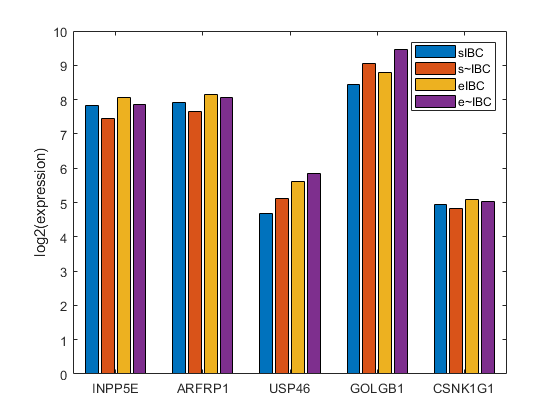

[~,Itop5]=sort(dpvals.double(:,1));
Itop5 = Itop5(1:5); % return the index of top 5
top5avg = zeros(5,4);
top5std = zeros(5,4);
for gi=1:4
	top5avg(:,gi) = mean(gse.Data.double(Itop5, Igroups==gi),2);
	top5std(:,gi) = std(gse.Data.double(Itop5, Igroups==gi),[],2);
end

figure;
bar(top5avg); % pay attention to sIBC and s~IBC
ylabel('log2(expression)')
h=gca; h.XTickLabel=gse.Data.rownames(Itop5);
legend(groupnames);

## Volcano Plot (Stroma_IBC vs Stroma_noibc)

pvalue is good to know, but we usually also want to know the fold changes (How different the average expression is between groups).  **Select significant genes with certain fold changes.**

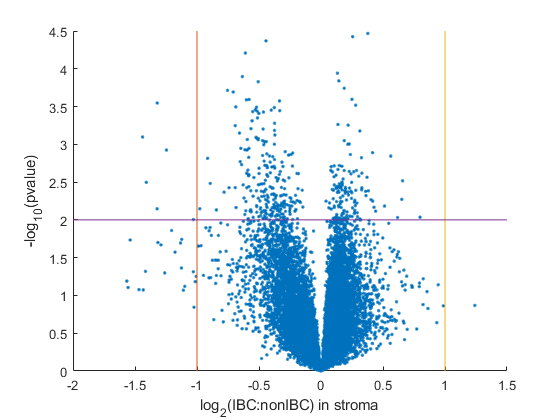

% Note that this GSE data is already log2-transformed. So, calculation of
% fold change should involve a subtraction, not a division!
% log2fc = ( mean(d(:,Istroma_ibc),2) ./ mean(d(:, Istroma_nonibc),2) );

% Average across the patients
log2fc = mean(gse.Data(:, mask.stroma_ibc), 2) - mean(gse.Data(:, mask.stroma_noibc), 2);

% Create Figure
figure;
scatter(log2fc, -log10(dpvals(:,1)), '.'); 
% dpvals is less than 1. convert it to positive with -log10. 
% The higher(-log10(dpvals(:,1)), the lower dpvals, the more significant it is.  
xlabel('log_2(IBC:nonIBC) in stroma'), ylabel('-log_{10}(pvalue)');

% mark fc>= (log2(2)) and pvalue<=0.01. -log10(-0.01)=2  
% log2fc=log2(a/b)=1 expression of a is 2 times more tha the b  
hold on;
plot(log2([0.5 0.5]), ylim, log2([2 2]), ylim)
plot(xlim, -log10([.01 .01]))

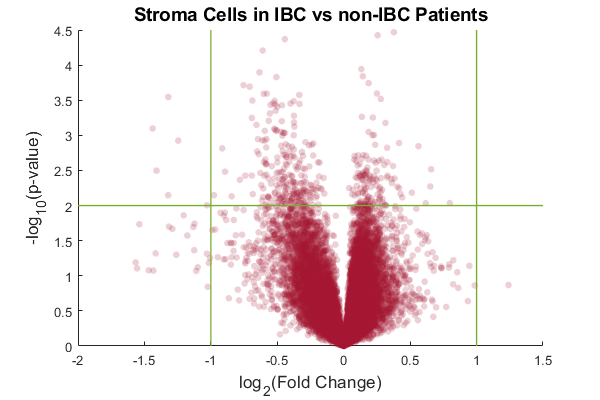

% Custom function
DGEvolcano(log2fc, dpvals(:,1), 'main', 'Stroma Cells in IBC vs non-IBC Patients')

Print the top 5 genes, now with fold change. log2fc is not easy to interpert. let's convert it to negative fold change.

So, a negfc=2 will mean IBC is 2-fold compared to nonIBC and negfc=-2 will mean IBC is half of nonIBC.

negfc = 2.^log2fc; 
%  convert the log2 fold change to the true value: 
% negfc=2^1=2 (log2fc =1), negfc=2^0=1(log2fc =0), negfc=2^(-1)= 0.5 (log2fc =-1).
negfc(negfc<1) = - 1./negfc(negfc<1); 
% convert all negfc<1 to a negative number of -1./negfc(negfc<1)
% negfc=2^(-1)= 0.5 (log2fc =-1), the new negfc =-1/0.5=-2
% which means Istroma_ibc is expressing less than Istroma_nonIBC
% negfc>1  means Istroma_ibc is expressing more Istroma_nonIBC
% Add the foldchange information to the dpvals object:
dpvals=[dpvals bioma.data.DataMatrix(negfc,'ColNames',{'negfc'})];
% Select the genes with pvalue<=0.01 and FC>=1.5.
I = dpvals(:,'p-values')<=0.01 & abs(dpvals(:,'negfc'))>=1.5;
dsigfc = dpvals(I,:);

Matlab has a mavolcanoplot() tool that helps you explore significantly different genes for different pvalue and fold change cutoffs.

% mavolcanoplot(d.double(:,Istroma_ibc), d.double(:,Istroma_nonibc), dpvals.double(:,1),'Labels',d.rownames)

## Writing Data into Excel File

Create a cell array containing the data that you want to appear in the excel sheet

I = find(dpvals(:,1) <= 0.01);
nsig = numel(I);
xlsdata = cell(nsig, 3); % each row will contain genesymbol, pvalue, negfc
for i = 1:nsig
	gene = dpvals.rownames{I(i)};
	p = dpvals.double(I(i), 1);
	nfc = dpvals.double(I(i), 2);
	xlsdata(i, :) = {gene p nfc};
end

% Add header row
xlsdata = [ {'genesymbol', 'pvalue', 'negfc'}; xlsdata ];
xlswrite('stomaibc.xlsx', xlsdata, 'sig genes IBC - nonIBC');

## Data Analysis: Hierarchical Clustering (co-expressed)

Let's cluster genes and samples using hierarchical clustering. Clustering can be very time consuming, so let's only do it for a subset of the genes.

genevarfilter   [https://www.mathworks.com/help/bioinfo/ref/genevarfilter.html](https://www.mathworks.com/help/bioinfo/ref/genevarfilter.html)

clustergram  [https://www.mathworks.com/help/bioinfo/ref/clustergram.html](https://www.mathworks.com/help/bioinfo/ref/clustergram.html)

% One idea is to only keep the genes that vary most across samples
% (ignoring sample groups). This can be done using:
I = genevarfilter(gse.Data, 'Percentile', 99); % remove 99% of genes
d2 = gse.Data( I, : );

% Another option is to keep the genes that vary across sample groups. Since
% we already did differential gene expression analysis above, let's use the
% genes resulting from it. (Note that we only compared IBC vs nonIBC in
% stroma cells; one would really need to repeat the DGE analysis for other
% pairs of groups of samples, and use the union of all significant genes).
Isig = dpvals(:, 'p-values') <= 0.05;
d3 = gse.Data(Isig, :);
cg = clustergram(d3, 'standardize', 'Row');

## Data-Analysis: k-Means Clustering

k-means is another method to generate groups of genes.

kmeans [https://www.mathworks.com/help/stats/kmeans.html.](https://www.mathworks.com/help/stats/kmeans.html.) 

% returns a row vector of 1,2,3,4,5,6 which indicates which cluster each gene belongs.
Iclust = kmeans(d3, 6, 'dist', 'corr');

% Once you have the Iclust membership values, you can generate a bar plot
d2avgavg = zeros(6,4);
for  i = 1:6; for j = 1:4;
		d2avgavg(i,j) = mean(mean(d3(Iclust == i, Igroups == j)));
end; end

figure;
bar(d2avgavg); legend(groupnames);
xlabel('Gene Clusters')

## Data Analysis: Principal Component Analysis (PCA)

Each gene is a multi-dimensional vector (as many dimensions as the number of samples). We often want to visualize genes in a lower (2D) space. Let's use PCA to reudce data dimesnionality while preserving as much of the original information as possible.

d3 data is reduced to 547x546 (95 principal componenets)

pca() https://www.mathworks.com/help/stats/pca.html

`pc = pca(`[`X`](https://www.mathworks.com/help/stats/pca.html#bth9ibe-X)`)` returns the principal component coefficients, also known as loadings, for the *n*-by-*p* data matrix `X`. Rows of `X` correspond to observations and columns correspond to variables. The coefficient matrix is *p*-by-*p*. 

reduced: principal component reduced(scores) are the representations of `X` in the principal component space. Rows of reduced (`score)` correspond to observations, and columns correspond to components (principle 1 ....).

pcvars: the principal component variances

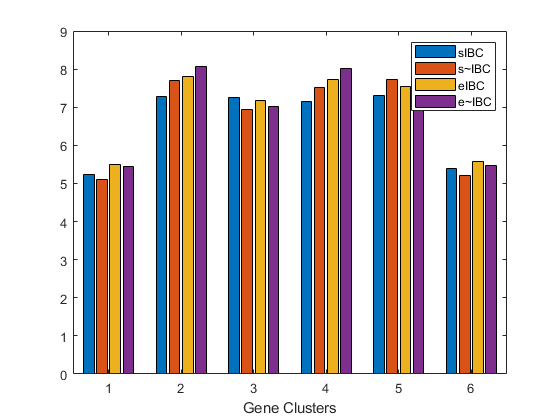

[coef, pc, pcvars] = pca(d3);
% coef - coefficients, loadings or weights - how the variables are combined
% reduced - principal components
% latent - variances for each principal component
% reduced has as many columns as the original data. But the first column
% now contains the most information (PC1), the second column contains the
% second most (PC2), etc. Let's use the first two columns to show genes on
% a figure


figure('Position', [0 0 600 400]); scatter(reduced(:, 1), reduced(:,2), 50, 'filled', 'MarkerFaceAlpha', 0.15);

We can combine the clustering and PCA and show the genes in different clusters with a different color.

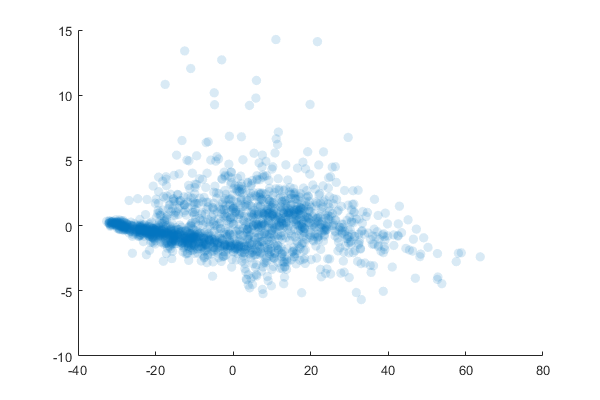

figure('Position', [0 0 600 400])
gscatter(reduced(:,1), reduced(:,2), Iclust);

% we can label the points using the text() function. Let's do that for 5
% random genes
l = randi(1000, [1 5]);
for i = 1:5
	text(reduced(l(i),1), reduced(l(i),2), d3.RowNames{l(i)}, 'FontWeight', 'bold', 'FontSize', 8)
end
% Whenever you show the results of PCA, you should report the amount of

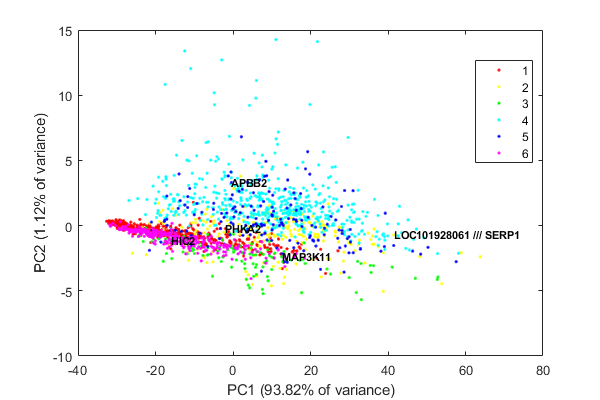

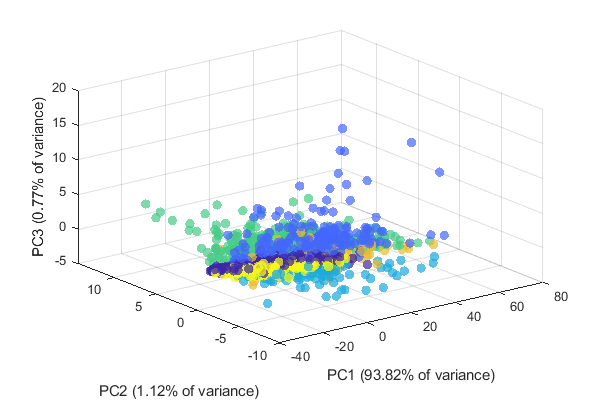

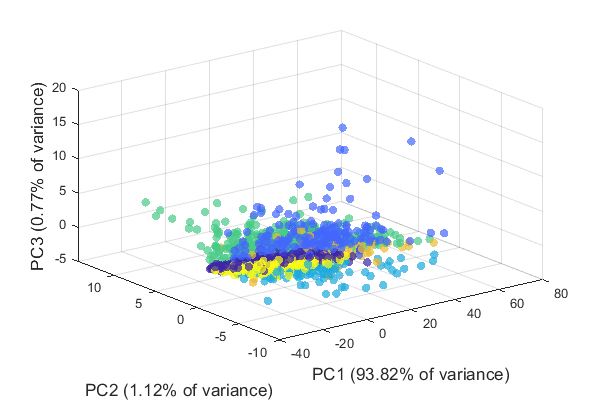

% variance captured by the reduced data.
pcvars = pcvars / sum(pcvars) * 100;
xlabel(sprintf('PC1 (%.2f%% of variance)', pcvars(1)))
ylabel(sprintf('PC2 (%.2f%% of variance)', pcvars(2)))
% 3-Dimensional Scatter
figure('Position', [0 0 600 400])
scatter3(reduced(:, 1), reduced(:, 2), reduced(:, 3), 50, Iclust, 'filled',...
	       'MarkerFaceAlpha', 0.7);
xlabel(sprintf('PC1 (%.2f%% of variance)', pcvars(1)))
ylabel(sprintf('PC2 (%.2f%% of variance)', pcvars(2)))
zlabel(sprintf('PC3 (%.2f%% of variance)', pcvars(3)))
% Custom function
plotPC(reduced, pcvars, 'groups', Iclust, 'dim', 3)